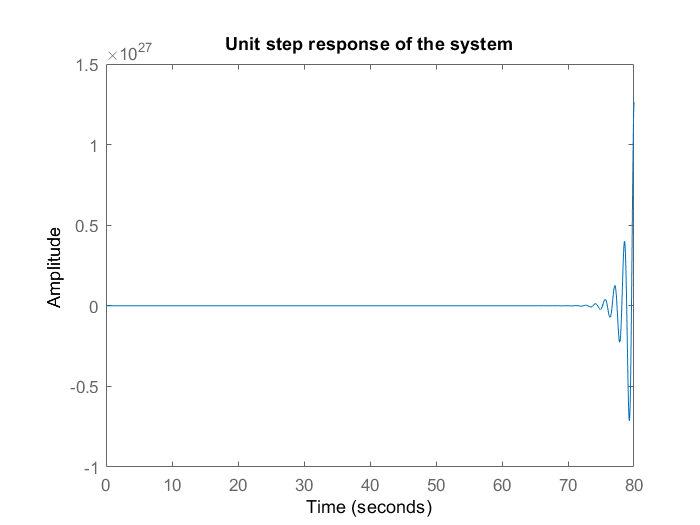

% Unit step and unit ramp response of a system
clc;
s=tf('s');
P=0.7;
G=2/(P*s+1);
F1=(1/s)*5*(G);
F2=feedback(F1,1);
F3=4*F2*(1/s);
F4=feedback(F3,1);
F4;
%unit step response and unit ramp response
step(F4)
title('Unit step response of the system')

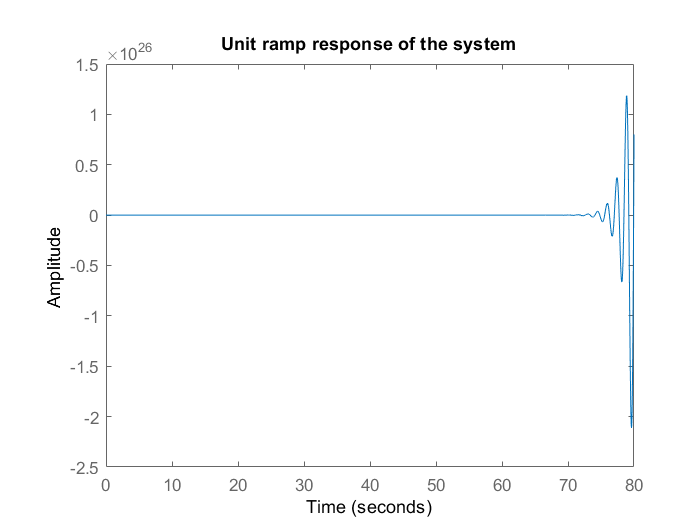

step(F4/s)
title('Unit ramp response of the system')

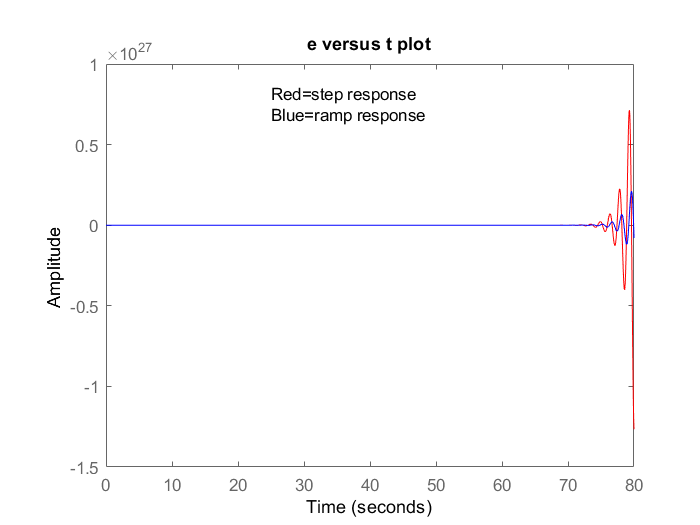

x1=F4;
r=1/s^2;
e=r-x1;
x2=s*x1;
x3=4*e-x2;
%plotting curves x1(t) versus t, x2(t) versus t, x3(t) versus t, and e(t) versus t
% for step and ramp response
step(e,'r')
hold on
step(e/s,'b')
txt={'Red=step response','Blue=ramp response'};
text(25,.75*10^27,txt)
title('e versus t plot')
hold off

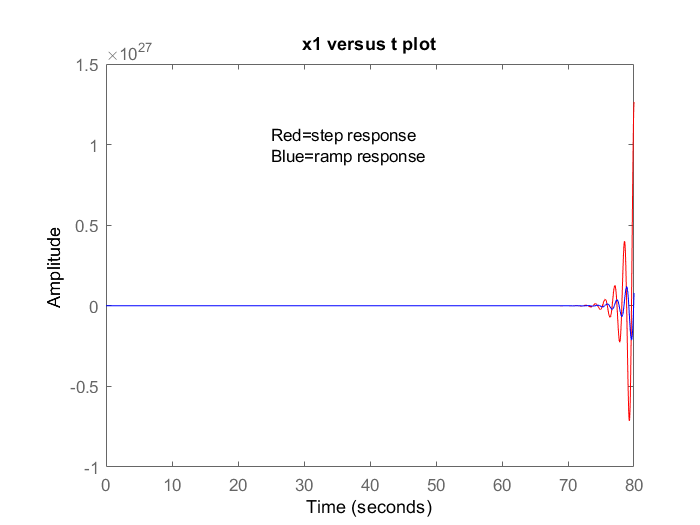

step(x1,'r')
hold on
step(x1/s,'b')
txt={'Red=step response','Blue=ramp response'};
text(25,1*10^27,txt)
title('x1 versus t plot')
hold off

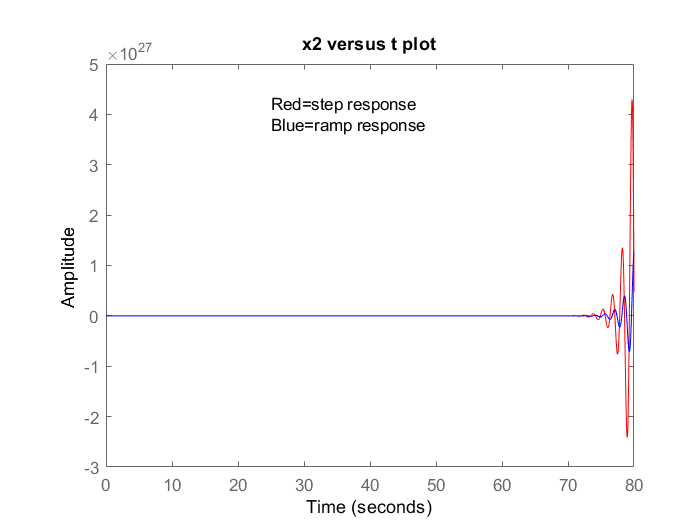

step(x2,'r')
hold on
step(x2/s,'b')
txt={'Red=step response','Blue=ramp response'};
text(25,4*10^27,txt)
title('x2 versus t plot')
hold off

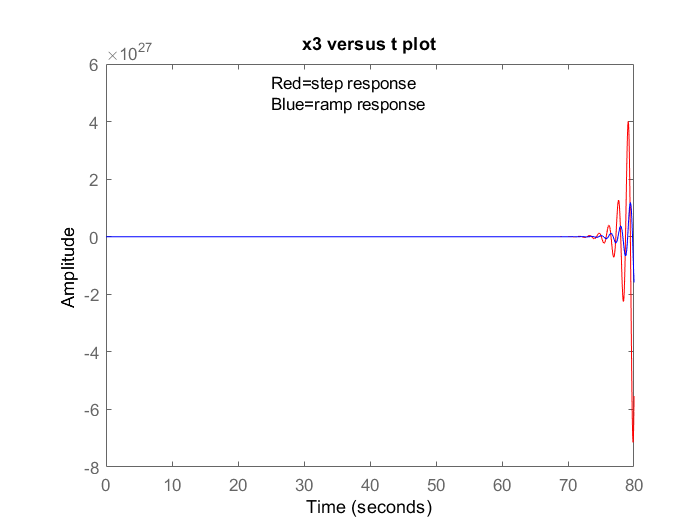

step(x3,'r')
hold on
step(x3/s,'b')
txt={'Red=step response','Blue=ramp response'};
text(25,5*10^27,txt)
title('x3 versus t plot')


% syms s;
% x1=40/(P*s^3+s^2+10*s+40);
% G1=2/(P*s+1);
% r=1/s^2;
% e=r-x1;
% x2=s*x1;
% x3=4*e-x2;
% x1=x2/s;
% step(e)
% title('e versus t plot')
% step(x1)
% title('x1 versus t plot')
% step(x2)
% title('x2 versus t plot')
% step(x3)
% title('x3 versus t plot')
% Y0=ilaplace(e);
% Y1=ilaplace(x1);
% Y2=ilaplace(x2);
% Y3=ilaplace(x3);
% fplot(Y0)
% title('e versus t plot')
% fplot(Y1)
% title('x1 versus t plot')
% fplot(Y2)
% title('x2 versus t plot')
% fplot(Y3)
% title('x3 versus t plot')